cAMPFreThroyVSsimBio

Shuai Yang

2023/3/14

对比理论与simBio模型的差异

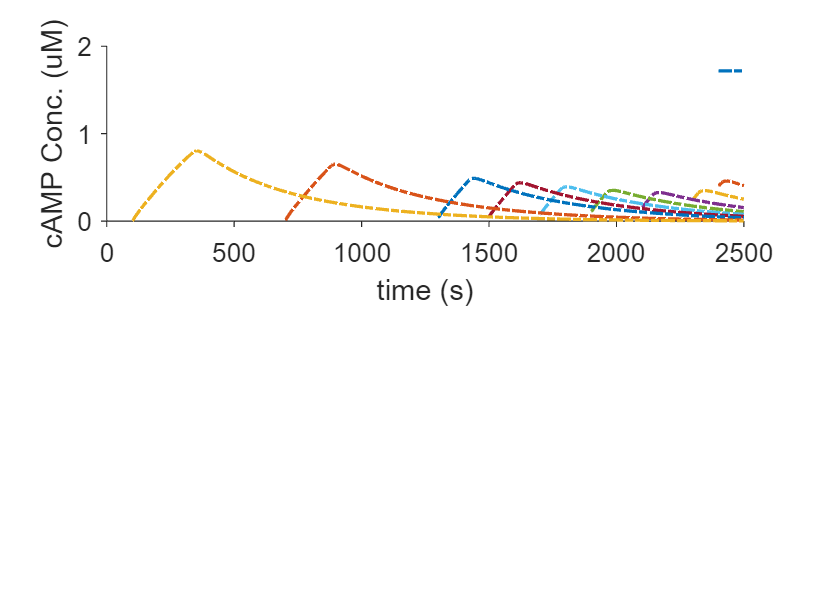

% outParaName = {'cAMP','cAMP-CpdA','cAMP-sensor','Vfr-cAMP','Vfr_cAMP2',...
%     'pVfr-Vfr','X_pY','X_pZ'};
% names = results.DataNames ;
% [Lia,Locb] = ismember(names,outParaName);
% outData = results.Data(:,Lia);
% outData1 = sum(outData,2);
% [t, x] = selectbyname(results, {'TF_X','Z_Pro','Y_Pro'});

Tset = [100,100,200,400,600,800,1000,1200,1800,2400];
f1 = figure;
ax1 = axes('Parent',f1);
subplt1 = subplot(2,1,1,'Parent',f1);
outParaName = {'cAMP'};
for iTset = 1:numel(Tset)
    result_each = results(iTset);
    names = result_each.DataNames ;
    [Lia,Locb] = ismember(names,outParaName);
    K = find(Lia);
    StopTime = result_each.Time(end);
    n = fix(StopTime/Tset(iTset));
    TF = result_each.Time>= Tset(iTset)*(n-1)&result_each.Time<= Tset(iTset)*n;
    t = result_each.Time(TF);
    t = t-t(1);  
    t_New = (2500-t(end))+t;% 末尾点对齐

    plot(t_New,result_each.Data(TF,K),'LineWidth',1.5,'LineStyle','-.','Parent',subplt1);
    hold on
end
set(subplt1,'Tickdir','out','Box','off','FontSize',12);

xlabel(subplt1,'time (s)')
ylabel(subplt1,'cAMP Conc. (uM)')

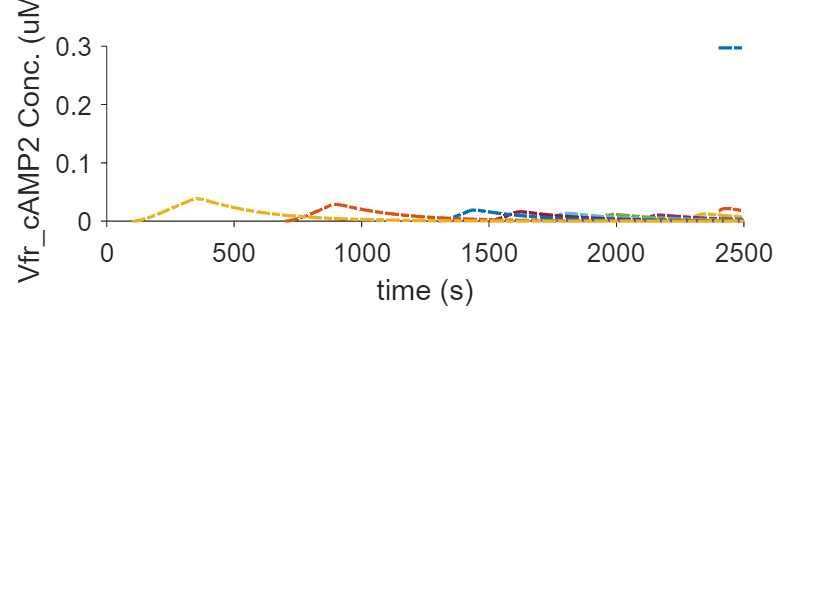


Tset = [100,100,200,400,600,800,1000,1200,1800,2400];
f1 = figure;
ax1 = axes('Parent',f1);
subplt1 = subplot(2,1,1,'Parent',f1);
outParaName = {'Vfr_cAMP2'};
for iTset = 1:numel(Tset)
    result_each = results(iTset);
    names = result_each.DataNames ;
    [Lia,Locb] = ismember(names,outParaName);
    K = find(Lia);
    StopTime = result_each.Time(end);
    n = fix(StopTime/Tset(iTset));
    TF = result_each.Time>= Tset(iTset)*(n-1)&result_each.Time<= Tset(iTset)*n;
    t = result_each.Time(TF);
    t = t-t(1);  
    t_New = (2500-t(end))+t;% 末尾点对齐

    plot(t_New,result_each.Data(TF,K),'LineWidth',1.5,'LineStyle','-.','Parent',subplt1);
    hold on
end
set(subplt1,'Tickdir','out','Box','off','FontSize',12);

xlabel(subplt1,'time (s)')
ylabel(subplt1,'Vfr_cAMP2 Conc. (uM)','Interpreter','none')

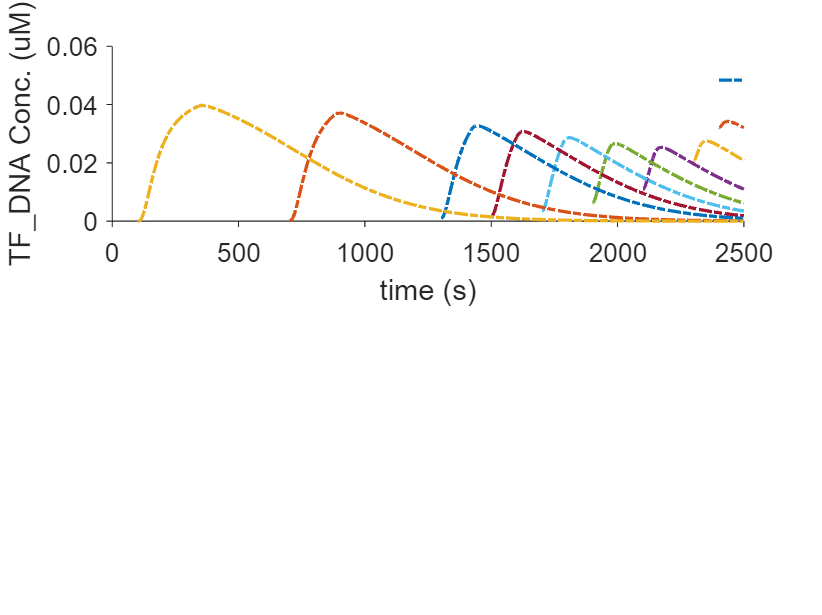


Tset = [100,100,200,400,600,800,1000,1200,1800,2400];
f1 = figure;
ax1 = axes('Parent',f1);
subplt1 = subplot(2,1,1,'Parent',f1);
outParaName = {'X_pY'};
for iTset = 1:numel(Tset)
    result_each = results(iTset);
    names = result_each.DataNames ;
    [Lia,Locb] = ismember(names,outParaName);
    K = find(Lia);
    StopTime = result_each.Time(end);
    n = fix(StopTime/Tset(iTset));
    TF = result_each.Time>= Tset(iTset)*(n-1)&result_each.Time<= Tset(iTset)*n;
    t = result_each.Time(TF);
    t = t-t(1);  
    t_New = (2500-t(end))+t;% 末尾点对齐

    plot(t_New,result_each.Data(TF,K),'LineWidth',1.5,'LineStyle','-.','Parent',subplt1);
    hold on
end
set(subplt1,'Tickdir','out','Box','off','FontSize',12);

xlabel(subplt1,'time (s)')
ylabel(subplt1,'TF_DNA Conc. (uM)','Interpreter','none')

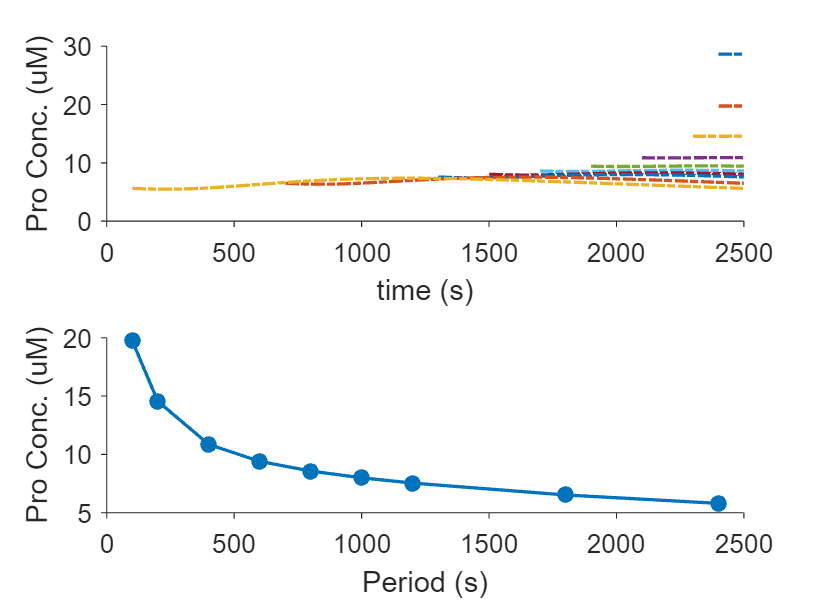

Tset = [100,100,200,400,600,800,1000,1200,1800,2400];
f1 = figure;
ax1 = axes('Parent',f1);
subplt1 = subplot(2,1,1,'Parent',f1);
subplt2 = subplot(2,1,2,'Parent',f1);
outParaName = {'Y_Pro'};
meanOut = NaN(size(Tset));
for iTset = 1:numel(Tset)
    result_each = results(iTset);
    names = result_each.DataNames ;
    [Lia,Locb] = ismember(names,outParaName);
    K = find(Lia);
    StopTime = result_each.Time(end);
    n = fix(StopTime/Tset(iTset));
    TF = result_each.Time>= Tset(iTset)*(n-1)&result_each.Time <= Tset(iTset)*n;
    t = result_each.Time(TF);
    t = t-t(1);  
    t_New = (2500-t(end)) + t;% 末尾点对齐
    plot(t_New,result_each.Data(TF,K),'LineWidth',1.5,'LineStyle','-.','Parent',subplt1);
    hold(subplt1,'on');
    meanOut(iTset) = mean(result_each.Data(TF,K));

end

hold(subplt1,'off');

hold(subplt2,'on');
plot(Tset(2:end),meanOut(2:end),'Marker','o','MarkerSize',6, ...
    'MarkerFaceColor',[0,0.45,0.74], ...
    'Color',[0,0.45,0.74],'LineWidth',1.5,'Parent',subplt2);
hold(subplt2,'off');

set(subplt1,'Tickdir','out','Box','off','FontSize',12);
set(subplt2,'Tickdir','out','Box','off','FontSize',12);

xlabel(subplt1,'time (s)')
ylabel(subplt1,'Pro Conc. (uM)','Interpreter','none')

xlabel(subplt2,'Period (s)')
ylabel(subplt2,'Pro Conc. (uM)','Interpreter','none')